# Solving the System using State Space model

clear;
clc;

parameters
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



A = [   0,     1,    0,    0;
     -k1/m1,-c1/m1,k1/m1,c1/m1;
        0,     0,    0,    1;
      k1/m2,c1/m2,-(k1+k2)/m2,-(c1+c2)/m2]

A =            0           1           0           0
       -1000         -10        1000          10
           0           0           0           1
         100           1       -1100         -11


B  = [0;1;0;0]

B =      0
     1
     0
     0


C1 = [1,0,0,0]

C1 =      1     0     0     0


C2 = [0,0,1,0]

C2 =      0     0     1     0


I = eye(4)

I =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


S = (inv(s*I-A))

S =
 
  From input 1 to output...
            s^3 + 21 s^2 + 1200 s + 1e04
   1:  ---------------------------------------
       s^4 + 21 s^3 + 2200 s^2 + 2e04 s + 1e06
 
              -1000 s^2 - 1e04 s - 1e06
   2:  ---------------------------------------
       s^4 + 21 s^3 + 2200 s^2 + 2e04 s + 1e06
 
                  100 s + 4.396e-12
   3:  ---------------------------------------
       s^4 + 21 s^3 + 2200 s^2 + 2e04 s + 1e06
 
          100 s^2 + 3.606e-13 s + 5.526e-10
   4:  ---------------------------------------
       s^4 + 21 s^3 + 2200 s^2 + 2e04 s + 1e06
 
  From input 2 to output...
                  s^2 + 11 s + 1100
   1:  ---------------------------------------
       s^4 + 21 s^3 + 2200 s^2 + 2e04 s + 1e06
 
          s^3 + 11 s^2 + 1100 s + 2.739e-10
   2:  ---------------------------------------
       s^4 + 21 s^3 + 2200 s^2 + 2e04 s + 1e06
 
                       s + 100
   3:  ---------------------------------------
       s^4 + 21 s^3 + 2200 s^2 + 2e04 s + 1

Tf1 = C1*S*B

Tf1 =
 
             s^2 + 11 s + 1100
  ---------------------------------------
  s^4 + 21 s^3 + 2200 s^2 + 2e04 s + 1e06
 
Continuous-time transfer function.



Tf2 = C2*S*B

Tf2 =
 
                  s + 100
  ---------------------------------------
  s^4 + 21 s^3 + 2200 s^2 + 2e04 s + 1e06
 
Continuous-time transfer function.



## For Step Function with magnitude 5

U = 5/s

U =
 
  5
  -
  s
 
Continuous-time transfer function.



X1_s = Tf1*U

X1_s =
 
              5 s^2 + 55 s + 5500
  -------------------------------------------
  s^5 + 21 s^4 + 2200 s^3 + 2e04 s^2 + 1e06 s
 
Continuous-time transfer function.



X2_s = Tf2*U

X2_s =
 
                   5 s + 500
  -------------------------------------------
  s^5 + 21 s^4 + 2200 s^3 + 2e04 s^2 + 1e06 s
 
Continuous-time transfer function.



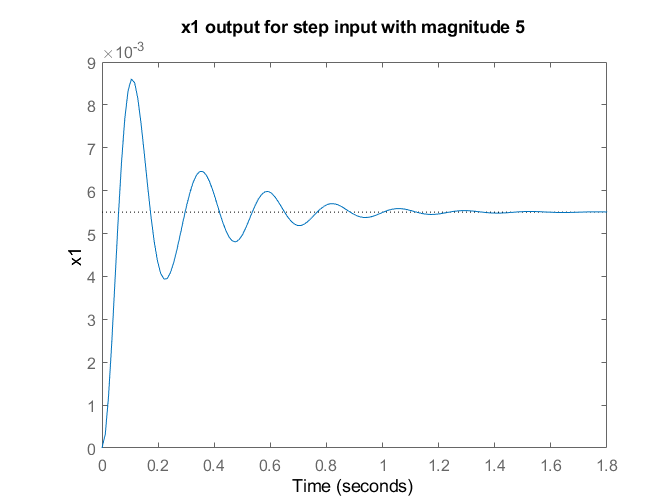

step(Tf1*5)
ylabel("x1")
title("x1 output for step input with magnitude 5")

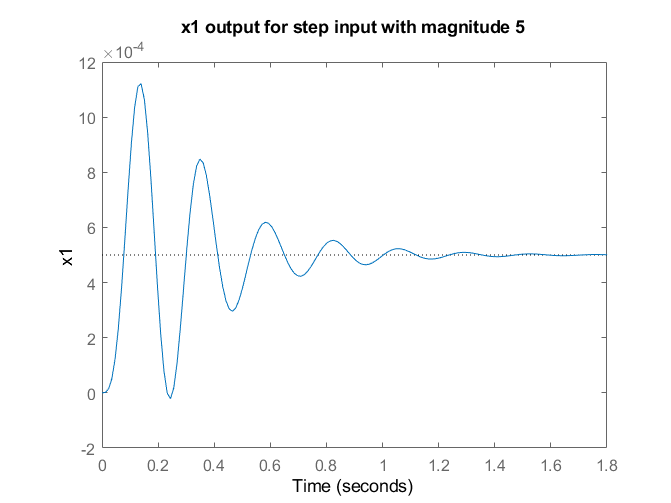

step(Tf2*5)
ylabel("x1")
title("x1 output for step input with magnitude 5")

## For Sine Function with amplitude 3 and frequency 10

Sine_s = 3*10/(s*s+10*10) %Laplace of sine

Sine_s =
 
     30
  ---------
  s^2 + 100
 
Continuous-time transfer function.



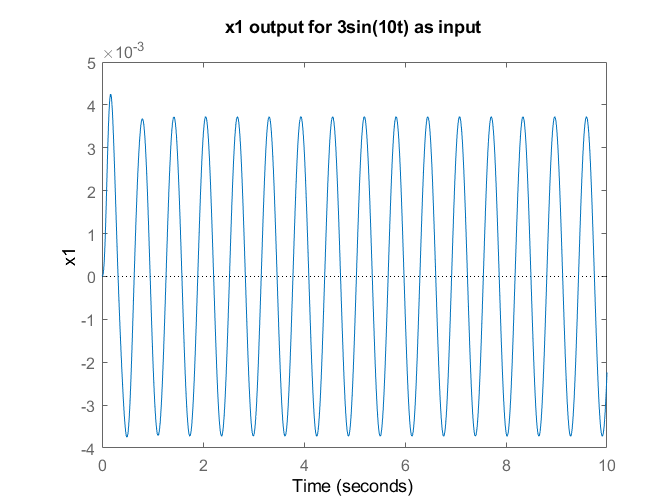

step(Tf1*s*Sine_s,Tend) % Multiplied with "s" to remove the step from step response.
ylabel("x1")
title("x1 output for 3sin(10t) as input")

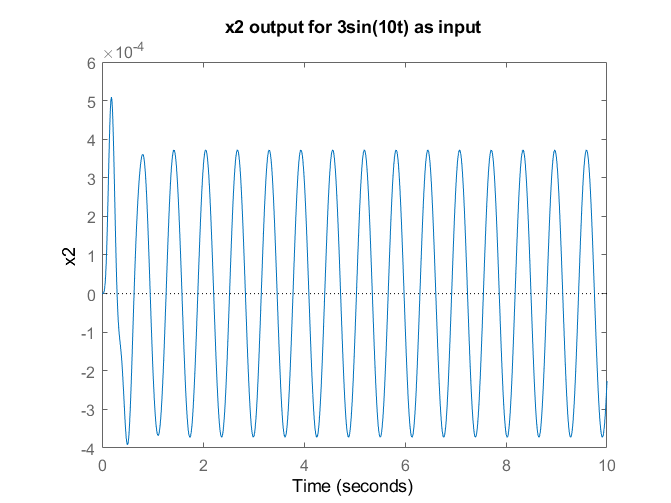

step(Tf2*s*Sine_s,Tend)
ylabel("x2")
title("x2 output for 3sin(10t) as input")